% PHASE 1: Define the Motor Plant Model

K = 1;       % Motor Gain
tau = 0.5;   % Time Constant 

% Create the Transfer Function G(s):
G = tf(K, [tau 1]);

% This shows the "raw" motor behavior without a controller.
figure(1);
step(G);
grid on;
title('Open-Loop Motor Step Response');
xlabel('Time');
ylabel('Motor Speed (normalized)');
info_pid = stepinfo(pid);
fprintf('\n--- PID Controller Performance ---\n');


--- PID Controller Performance ---


fprintf('Rise Time:     %.2f s (Target: < 1.0s)\n', info_pid.RiseTime);

Rise Time:     0.00 s (Target: < 1.0s)


fprintf('Overshoot:     %.2f%% (Target: < 10%%)\n', info_pid.Overshoot);

Overshoot:     0.00% (Target: < 10%)


fprintf('Settling Time: %.2f s\n', info_pid.SettlingTime);

Settling Time: 0.00 s


fprintf('----------------------------------\n');

----------------------------------


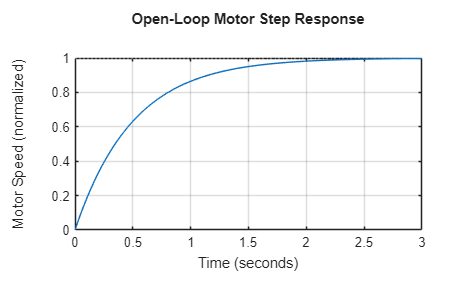


% Save Result
if ~exist('results', 'dir'), mkdir('results'); end
saveas(gcf, 'results/open_loop_response.png');